load('KINOVAGen3GripperColl.mat'); 

currentRobotJConfig = homeConfiguration(robot)

currentRobotJConfig =      0     0     0     0     0     0     0


coordinator = CoordinatorPickPlace(robot,currentRobotJConfig, "gripper")

coordinator =   CoordinatorPickPlace with properties:

                 FlowChart: []
                     Robot: [1×1 rigidBodyTree]
                     World: {}
                     Parts: {}
                 Obstacles: {}
             DetectedParts: {}
          RobotEndEffector: "gripper"
       CurrentRobotJConfig: [0 0 0 0 0 0 0]
    CurrentRobotTaskConfig: [4×4 double]
                  NextPart: 0
               PartOnRobot: 0
       HomeRobotTaskConfig: []
               PlacingPose: []
                 GraspPose: []
                    Figure: [1×1 interactiveRigidBodyTree]
                  TimeStep: 0.1000
               MotionModel: [1×1 jointSpaceMotionModel]
                 NumJoints: 7
          NumDetectionRuns: 0
                PathHandle: []



coordinator.HomeRobotTaskConfig = trvec2tform([0.1, -0.4, 0.5])*axang2tform([1 0 0 3*pi/4])

coordinator =   CoordinatorPickPlace with properties:

                 FlowChart: []
                     Robot: [1×1 rigidBodyTree]
                     World: {}
                     Parts: {}
                 Obstacles: {}
             DetectedParts: {}
          RobotEndEffector: "gripper"
       CurrentRobotJConfig: [0 0 0 0 0 0 0]
    CurrentRobotTaskConfig: [4×4 double]
                  NextPart: 0
               PartOnRobot: 0
       HomeRobotTaskConfig: [4×4 double]
               PlacingPose: []
                 GraspPose: []
                    Figure: [1×1 interactiveRigidBodyTree]
                  TimeStep: 0.1000
               MotionModel: [1×1 jointSpaceMotionModel]
                 NumJoints: 7
          NumDetectionRuns: 0
                PathHandle: []




coordinator.PlacingPose{1} = trvec2tform([[0.03 -0.8 0.2]])*axang2tform([0 -1 0 pi])

coordinator =   CoordinatorPickPlace with properties:

                 FlowChart: []
                     Robot: [1×1 rigidBodyTree]
                     World: {}
                     Parts: {}
                 Obstacles: {}
             DetectedParts: {}
          RobotEndEffector: "gripper"
       CurrentRobotJConfig: [0 0 0 0 0 0 0]
    CurrentRobotTaskConfig: [4×4 double]
                  NextPart: 0
               PartOnRobot: 0
       HomeRobotTaskConfig: [4×4 double]
               PlacingPose: {[4×4 double]}
                 GraspPose: []
                    Figure: [1×1 interactiveRigidBodyTree]
                  TimeStep: 0.1000
               MotionModel: [1×1 jointSpaceMotionModel]
                 NumJoints: 7
          NumDetectionRuns: 0
                PathHandle: []



coordinator.FlowChart = FlowChartPickPlace('coordinator', coordinator) 

coordinator =   CoordinatorPickPlace with properties:

                 FlowChart: [1×1 FlowChartPickPlace]
                     Robot: [1×1 rigidBodyTree]
                     World: {}
                     Parts: {}
                 Obstacles: {}
             DetectedParts: {}
          RobotEndEffector: "gripper"
       CurrentRobotJConfig: [0 0 0 0 0 0 0]
    CurrentRobotTaskConfig: [4×4 double]
                  NextPart: 0
               PartOnRobot: 0
       HomeRobotTaskConfig: [4×4 double]
               PlacingPose: {[4×4 double]}
                 GraspPose: []
                    Figure: [1×1 interactiveRigidBodyTree]
                  TimeStep: 0.1000
               MotionModel: [1×1 jointSpaceMotionModel]
                 NumJoints: 7
          NumDetectionRuns: 0
                PathHandle: []


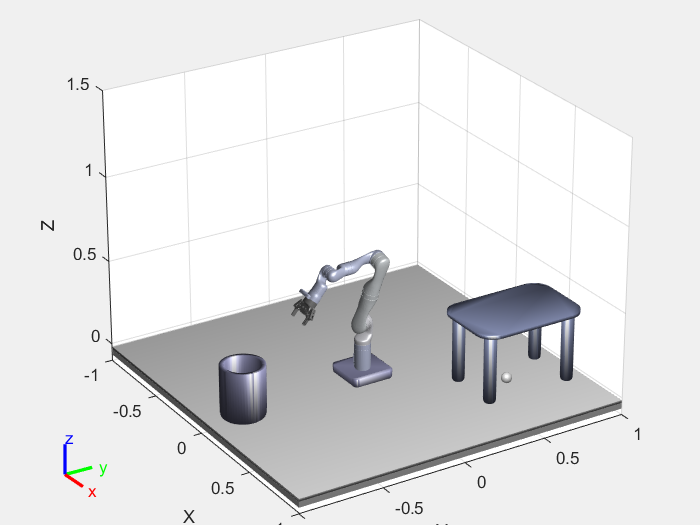


coordinator.FlowChart.startPickPlace;     